clear all;close all;clc;

## Import Cats/Dogs dataset

% Locate the csv file path
fileDir = 'C:\Users\kimok\OneDrive\Desktop\EELU\4th Year\Graduation Project\Datasets\final scratch dataset dog vs cat\';
% Load
cats = csvread([fileDir 'cat.csv'])';
dogs = csvread([fileDir 'dog.csv'])';
label = csvread([fileDir 'labels160.csv']);

% Concatenate matrices
X = [cats;dogs];
% List each sample to it's corresponding target output
xPlusLabels = [X(:, 1:4096), label, X(:, 4097:end)];

## Exploration Analysis

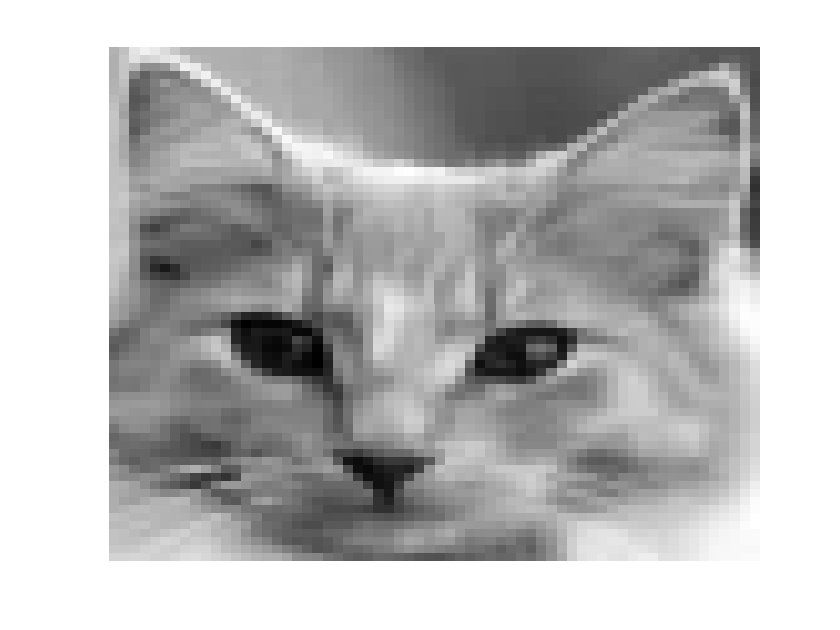

% Read a single image from the datastore
figure;
imagesc(reshape(X(61,:),64,64))
colormap("gray");
axis off;

## Reshape and display all cats

% uncomment to display all images
% figure;
% for i = 1:80
%     subplot(8,10,i);
%     cat = X(i,:);
%     imagesc(reshape(cat,64,64));
%     colormap("gray");
%     title(sprintf("cat %i",i));
%     axis off;
% end

## Reshape and display all cats

% uncomment to display all images
% figure;
% for i = 81:160
%     subplot(8,10,i-80);
%     dog = X(i,:);
%     imagesc(reshape(dog,64,64));
%     colormap("gray");
%     title(sprintf("dog %i",i));
%     axis off;
% end

## Mean Cats/Dogs

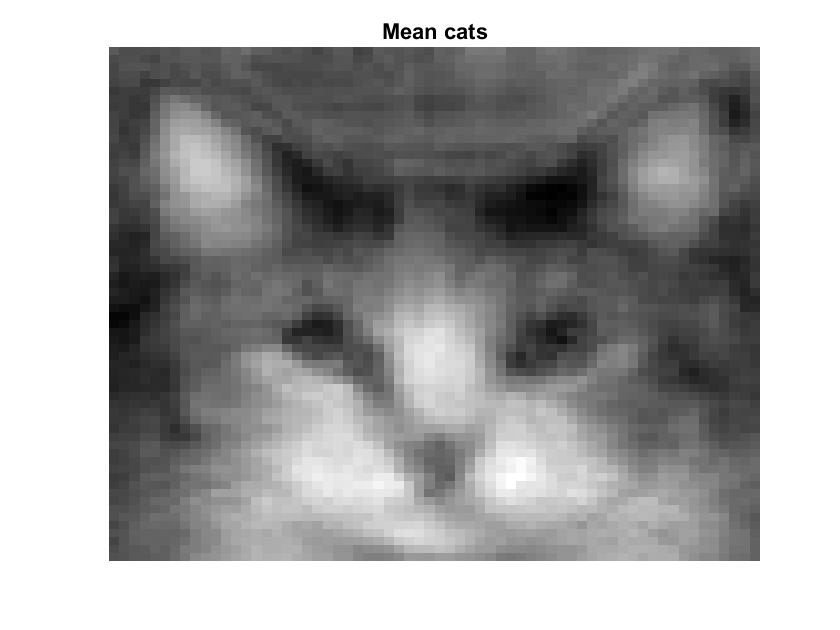

meanCat = mean(X(1:80,:),1);
figure;
imagesc(reshape(meanCat,64,64));
colormap("gray");
title("Mean cats");
axis off;

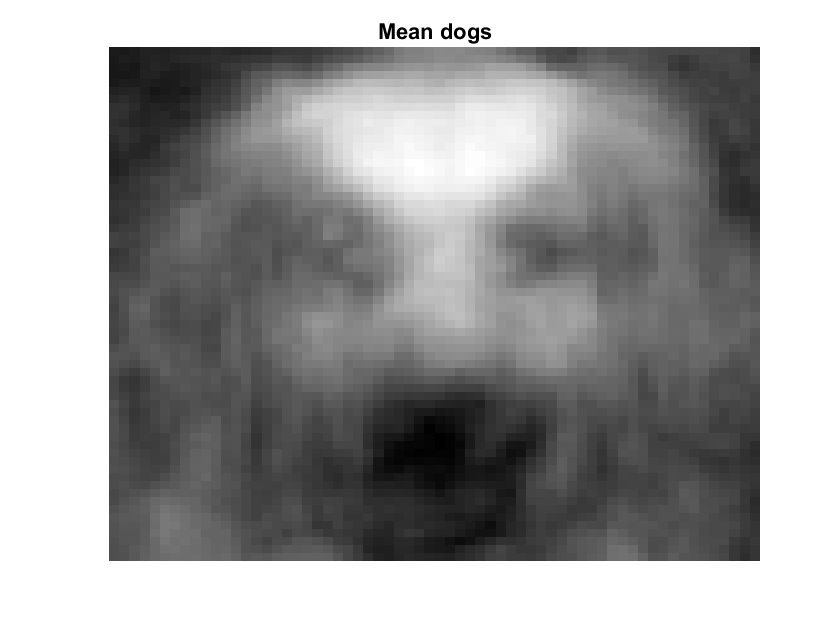

meanDog = mean(X(81:160,:),1);
figure;
imagesc(reshape(meanDog,64,64));
colormap("gray");
title("Mean dogs");
axis off;

## Mean all cats/dogs

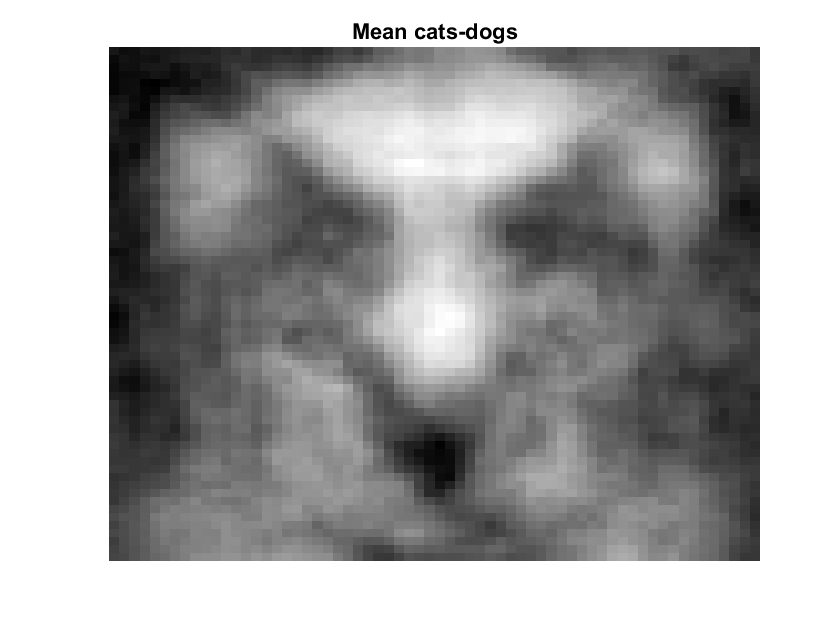

meanall = mean(X(1:160,:),1);
figure;
imagesc(reshape(meanall,64,64));
colormap("gray");
title("Mean cats-dogs");
axis off;

## Shuffle dataset for better performance in NN

% % Assign indices position for each sample (X)
% rng(3) % Fixed seed to stabilize results
% numSamples = size(xPlusLabels, 1);
% shuffledIndices = randperm(numSamples);
% X_Shuffled = xPlusLabels(shuffledIndices, :);
% label_shuffled = X_Shuffled(:,4097);

## Apply PCA

[coeff, score,latent,~,explained,mu] = pca(X);  

## Plot cumulative sum of Eignvalues

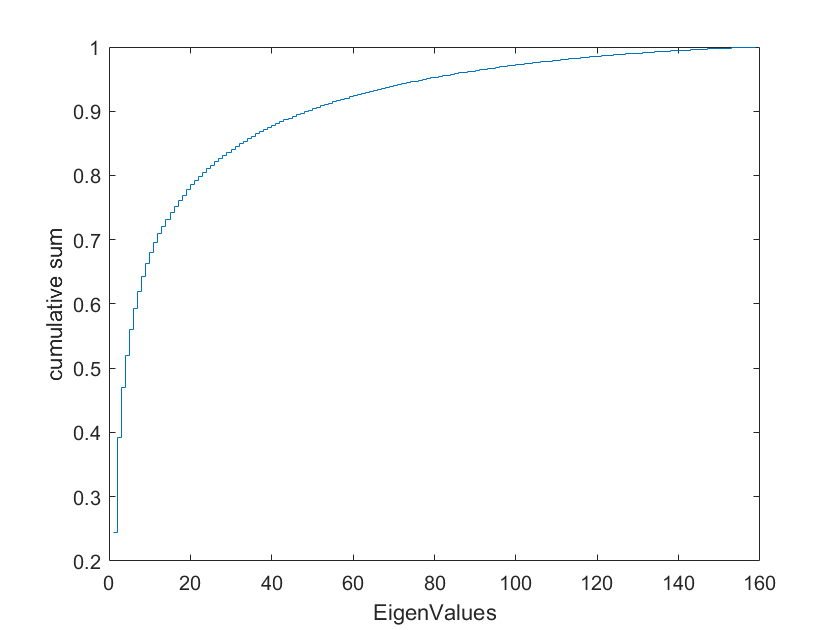

figure;
latent = latent/sum(latent);
stairs(cumsum(latent));
xlabel("EigenValues");
ylabel("cumulative sum");

## Scree plot

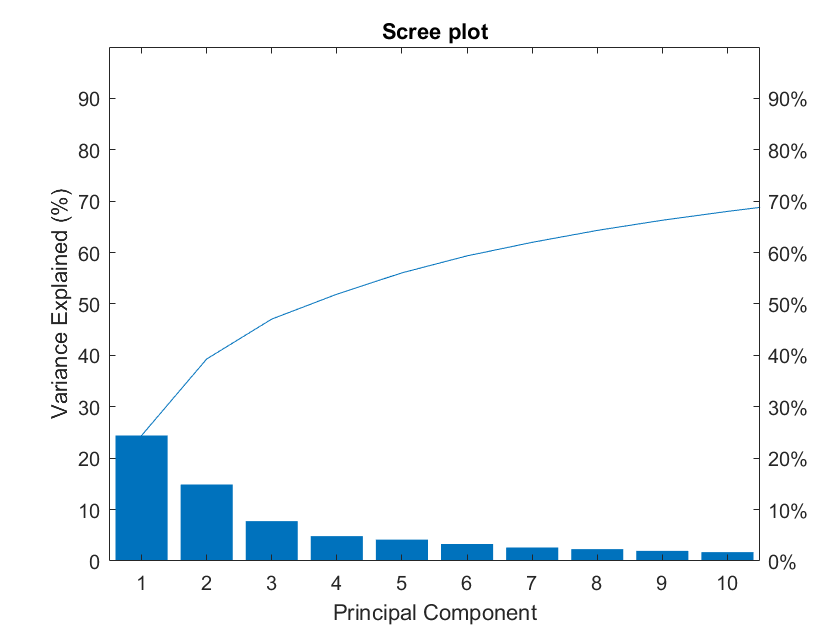

figure;
pareto(explained);
xlabel('Principal Component');
ylabel('Variance Explained (%)');
title("Scree plot");

## First EigenPet

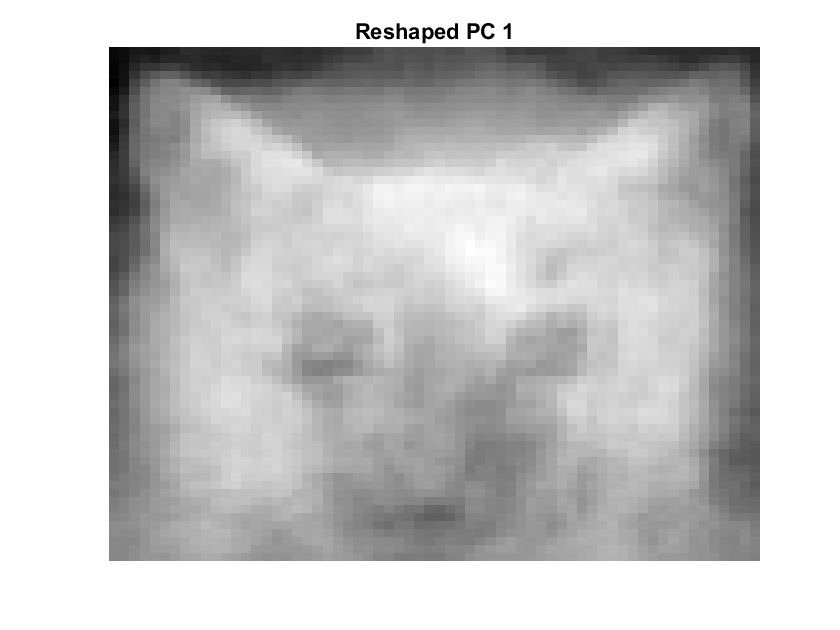

pc1 = coeff(:,1);
figure;
imagesc(reshape(pc1,64,64));
colormap("gray");
title("Reshaped PC 1");
axis off;

## Visualize different eigenpets

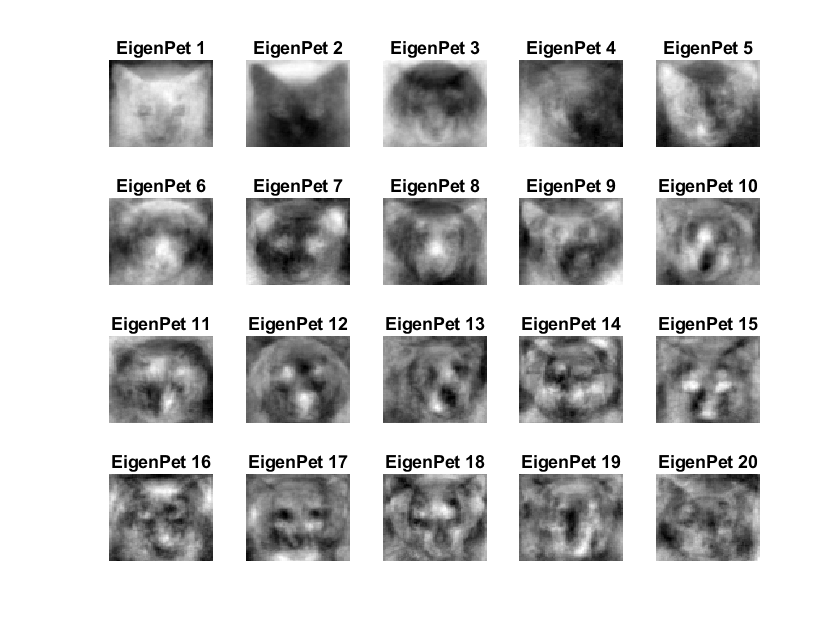

figure;
for i = 1:20
    subplot(4,5,i);
    pc = coeff(:,i);
    imagesc(reshape(pc,64,64));
    colormap("gray");
    title(sprintf("EigenPet %i",i));
    axis off;
end

## Scatter plot first three PCs

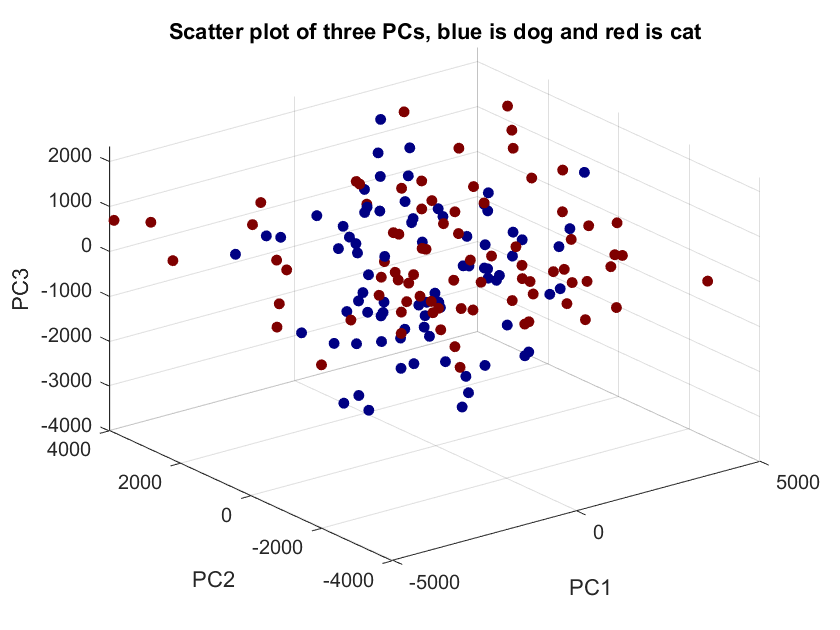

T = score(:,1:3);
figure;
scatter3(T(:,1),T(:,2),T(:,3),30,label,"filled");
xlabel("PC1"); 
ylabel("PC2");
zlabel("PC3");
colormap("jet");
title("Scatter plot of three PCs, blue is dog and red is cat");

## Scatter plot second three PCs

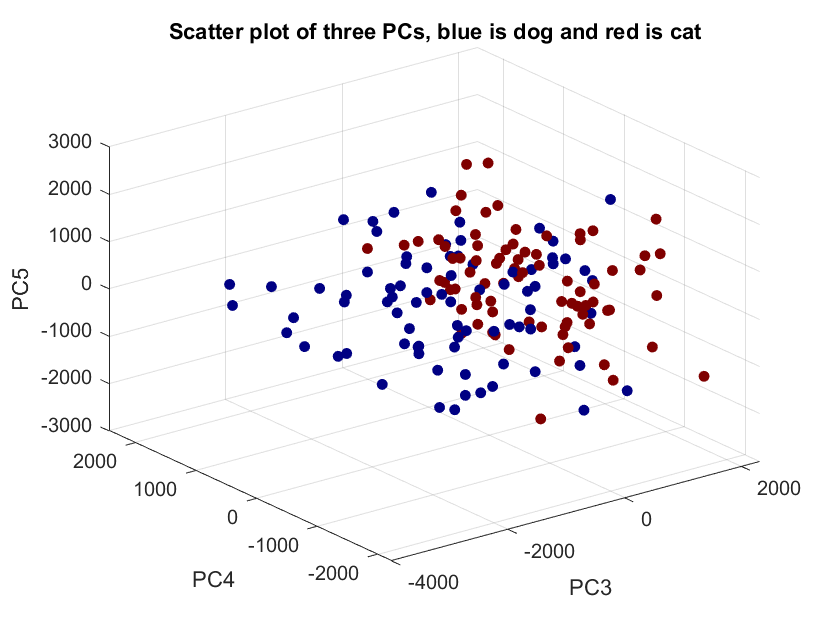

T = score(:,3:5);
figure;
scatter3(T(:,1),T(:,2),T(:,3),30,label,"filled");
xlabel("PC3");
ylabel("PC4");
zlabel("PC5");
colormap("jet");
title("Scatter plot of three PCs, blue is dog and red is cat");

## Reconstruction of original images through Eigenfaces

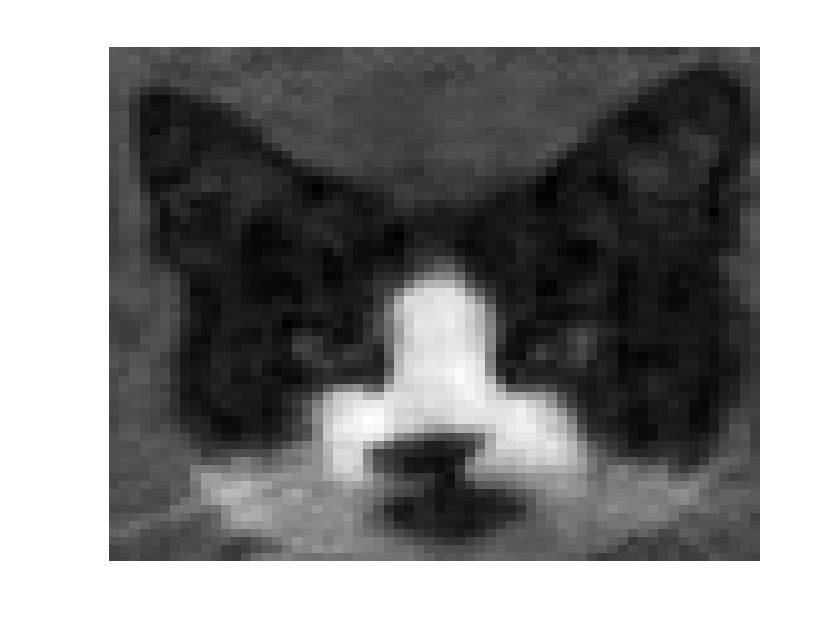

image = score(1,1:100) * coeff(:,1:100)' + mu;
figure;
imagesc(reshape(image,64,64))
colormap("gray")
axis off;

## Biplot

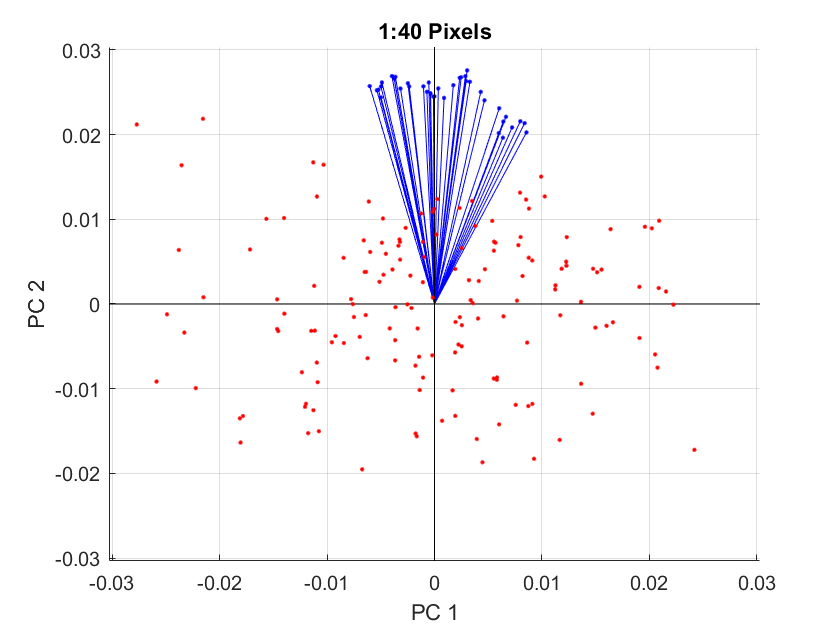

%% Biplot of first 40 transformed features
biplot(coeff(1:40,1:2),'scores',score(:,1:2),'varlabels',{});
xlabel('PC 1');
ylabel('PC 2');
title("1:40 Pixels");